UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

2025

# *Laboratory 5: Newton-Raphson and Secant Method*

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab5_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab5_name_lastname.rar*** and subject **Analisis_Lab5_name** to **jbacquin@uis.edu.co.**

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To implement the Newton-Raphson method in Matlab.

- To implement the Secant method in Matlab.

## Guide functions:

You will be introduced to some functions that may be useful for the development of this laboratory. You **DO NOT **have to use them if you do not requier them. This is with the purpose of providing a guide for you to understand Matlab and start coding more eficciently.

**Note:** Remember to save your Matlab functions as '.m' files.

- If an array X already exists, you can use it to increase the size of the array and append other elements to the array. For example, **X(end+1) = 5** increases the length of X by 1 and adds a new element to the end of X.

- **diff:** Use the diff function to approximate partial derivatives with the syntax **Y = diff(f)**, where f is a vector of function values evaluated on some domain, X.

- **Plot:** **plot(X,Y)** creates a 2D line plot of the data in Y versus the corresponding values in X.

You can change the color or style of lines or add markers by including an optional line specification when calling the plot function. For example:

':' represents a dotted line.

'g:' represents a green dotted line.

'g:*' represents a green dotted line with star markers.

'*' represents star markers without a line.

- **hold on:** hold on sets the axis hold state to on, which preserves the current axis graphs so that new graphs added to the axes do not override existing graphs.

- **hold off:** hold off sets the hold state of the axes to off so that new graphs added to the axes will clear existing graphs and reset all axis properties.

## **Implementing **

- **(1.0 points)** Create a Matlab function called *my_newton_function_name_lastname()* to find the root of a function using the Newton-Raphson method. The arguments of the function must be: the function to be evaluated $f\left(x\right)$ (as an inline function), the initial point [$p_0$], the derivate of the function $f^{\prime } \left(x\right)$ (as an inline function), and the stopping criteria (the number of iterations or the error). Find the three roots of the function $f\left(x\right)=x^3 +13x^2 -297\ldotp 5x+0\ldotp 00000375e^x$. **You have to choose a proper initial point for each root.  **

                Include the prints:

                - $k:\textrm{Number}\;\textrm{of}\;\textrm{current}\;\textrm{iteration}$

                - $p_k :\mathrm{Value}\;\mathrm{of}\;\mathrm{the}\;\mathrm{root}\;\mathrm{at}\;\mathrm{iteration}\;k$

                - $f\left(p_k \right):\textrm{Value}\;\textrm{of}\;\textrm{the}\;\textrm{function}\;\textrm{evaluated}\;\textrm{in}\;p_k$

                -$f^{\prime } \left(p_k \right):\textrm{Value}\;\textrm{of}\;\textrm{the}\;\textrm{derivative}\;\textrm{evaluated}\;\textrm{in}\;p_k$

                -$\frac{|p_k -p_{k-1} |}{|p_k |}:\textrm{Relatvie}\;\textrm{error}$

syms x
fun = @(x) x.^3 + 13*x.^2 - 297.5*x + 0.00000375;
der = matlabFunction(diff(fun(x), x));
stop = [100, 1e-6];    % iteraciones y tolerancia
p0 = 0;                % punto inicial (cámbialo según la raíz que quieras)
root = my_newton_function_name_lastname(fun, p0, der, stop);

Iter	 p_k		 f(p_k)		 f'(p_k)		 Error Relativo
1	 0.000000	 3.750000e-06	 -2.975000e+02	 1.000000e+00
2	 0.000000	 2.065532e-15	 -2.975000e+02	 5.508086e-10


- **(0.7 points) **Create a Matlab function called *my_visual_newton_function_name_lastname()* to visualize the behaviour of the Newton method. The arguments of the function must be: the function to be evaluated $f\left(x\right)\;$(as an inline function), the initial point [$p_0$], the derivate of the function, $\textrm{fp}\left(x\right)$, and the number of iterations. 

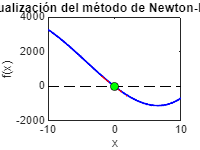

my_visual_newton_function_name_lastname(fun,p0,der,stop);

- **(1.0 points) **Create a Matlab function called *my_Secant_function_name_lastname()* to find the root of a function using the Secant method. The arguments of the function must be: the function to be evaluated $f\left(x\right)$ (as an inline function), and two  initial points [$p_{0,} {\;p}_1$], and the stopping criteria (the number of iterations or the error). Find a root of the function $f\left(x\right)=x^3 +-3x+2$, starting form $p_{0\;} =-2\ldotp 6\;\textrm{and}\;p_1 =-2\ldotp 4$ 

% Definir función
fun = @(x) x.^3 - 3*x + 2;

% Valores iniciales
p0 = -2.6;
p1 = -2.4;

% Criterio de parada: 100 iteraciones, tolerancia 1e-6
stop = [100, 1e-6];

% Llamada a la función
root = my_secant_function_name_lastname(fun, p0, p1, stop);

Iter	 p_k		 f(p_k)		 Error Relativo
1	 -2.106599	 -1.028782e+00	 1.392771e-01
2	 -2.022641	 -2.068601e-01	 4.150888e-02
3	 -2.001511	 -1.361358e-02	 1.055718e-02
4	 -2.000023	 -2.028314e-04	 7.442720e-04
5	 -2.000000	 -2.041724e-07	 1.125690e-05
6	 -2.000000	 -3.065992e-12	 1.134274e-08


- **(0.7 points) **Create a Matlab function called *my_visual_Secant_function_name_lastname()* to find the root of a function using the Secant method.

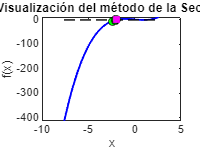

% Definir función
fun = @(x) x.^3 - 3*x + 2;

% Valores iniciales
p0 = -2.6;
p1 = -2.4;

% Número de iteraciones a visualizar
stop = 6;

% Llamar función visual
my_visual_secant_function_name_lastname(fun, p0, p1, stop);

## **Multiple roots**

**(1.0 points) **Use the Newton-Raphson method for the following equation $f\left(x\right)=x^3 -3x+2=0$ to find the roots 

(a) r = -2  starting from p_0 = -2.4

(b) r = 1  starting from  p_0 = 1.2

r = -2 converge más rápido (raíz simple, convergencia cuadrática); r = 1 converge más lento (raíz doble, convergencia lineal).

**(0.6 points) **Please summarize the results by determining which root converges the fastest and explaining why.

La raíz r=−2 converge más rápido porque es una raíz simple, lo que permite que el método de Newton–Raphson tenga convergencia cuadrática. En cambio, la raíz r=1 es una raíz múltiple y por eso la convergencia se vuelve lineal, necesitando más iteraciones.